# Example 2

#### Problem OCP:


$$\min_{{x}(t),{u}(t),t_f} \int_0^{t_f} 1 d \tau $$


subject to:


$$
 \dot{{x}_1}(t) = x_2(t), \quad \dot{{x}_2}(t) = u(t), $$



$${x}_1(0)=-3, \quad x_2(0)=0, \quad {x}_1(t_f)=0, \quad {x}_2(t_f)=0,$$



$$ u(t) \leq a_{\max},   \quad -u(t) \leq -a_{\min}.   
$$


## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 45; % Order of approximation
CONSTANTS.amax = 5;
CONSTANTS.amin = -5;
CONSTANTS.x10 = -3;
CONSTANTS.x1f = 0;
CONSTANTS.x20 = 0;
CONSTANTS.x2f = 0;

### Initial Guess

N = CONSTANTS.N; 
%x1 = linspace(CONSTANTS.x0,CONSTANTS.xf,CONSTANTS.N+1)';
x1 = ones(N+1,1);
x2 = ones(N+1,1);
u = ones(N+1,1);
tf = 10;
x0 = [x1;x2;u;tf];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 1.679780 seconds.


### Plot

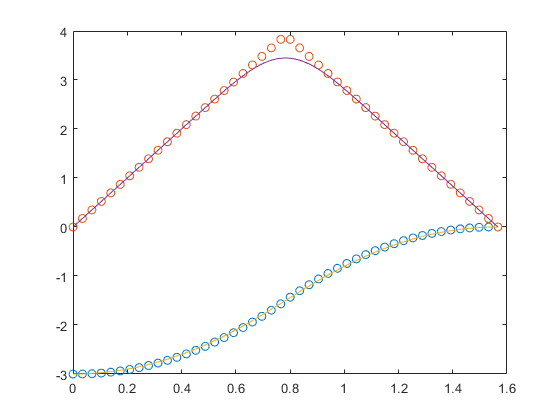

N = CONSTANTS.N;

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u = x(2*N+3:3*N+3);
tf = x(end);

[tnodes,w,Diff] = BeBOT(N,tf);
t = linspace(0,tf,1000);

figure
plot(tnodes,x1,'o'); hold on
plot(tnodes,x2,'o');
plot(t,BernsteinPoly(x1',t));
plot(t,BernsteinPoly(x2',t));

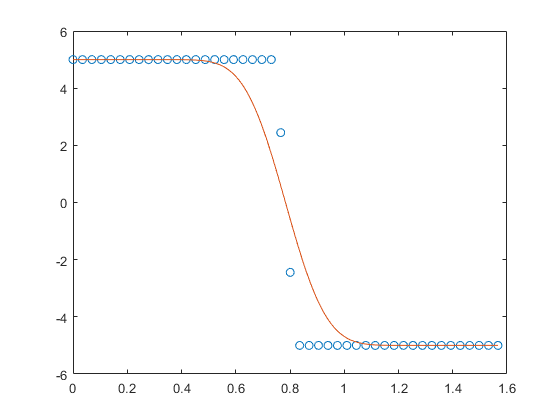


figure
plot(tnodes,u,'o'); hold on
plot(t,BernsteinPoly(u',t));

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u = x(2*N+3:3*N+3);
tf = x(end);

J = tf;
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u = x(2*N+3:3*N+3);
tf = x(end);

[tnodes,w,Diff] = BeBOT(CONSTANTS.N,tf);

dyn1 = x1'*Diff-x2';
dyn2 = x2'*Diff-u';

nonlcon1 = u' - CONSTANTS.amax;
nonlcon2 = -u' + CONSTANTS.amin;

c=[nonlcon1'; nonlcon2';];
ceq=[dyn1'; dyn2'; x1(1)-CONSTANTS.x10; x1(end)-CONSTANTS.x1f; x2(1)-CONSTANTS.x20; x2(end)-CONSTANTS.x2f];
end